# Gene expression part 01

## Credit: Griffin Chure & Manuel Razo

In this script, we'll learn some basic facts about images; from how to read them in matlab to the basic principles of thresholding segmentation. We will be analyzing a set of images that you'll have access to through the website. The way these files were named follows the following convention:

`operator_repressorCopy_channel_pos_#.tif`

So for example an image with the *O1 *operator, 260 repressors per cell in the YFP channel would be named as

`O1_R260_yfp_pos_xx.tif`

where `xx` represents one of the positions. Note that we use `01, 02` and so on rather than a single digit so that when the images are sorted position 2 doesn't come after position 19. It is in general a good practice to add these extra zeros to the left.

Our signal of interest is stored in the `yfp` channel, but we will be performing our segmentation in the `phase` image. Sometimes in our own research we have an extra channel (usually CFP or mCherry) that serves as a volume marker in order to find the cells. But using that type of segmentation requires a slightly more advance method, so for now simple thresholding in the phase contrast image should be good enough.

It is important to remember that an image is nothing but data - it is an array of points with a specific value called pixels. The values that these pixels can take is related to the construction of the camera and is measured as 'bit depth'. To determine the range of pixel values an N bit image can take, we simply need to compute  2N−1. This subtraction of 1 is because 0 can be a pixel value as well. For example, a 16-bit image can have pixels on the range of 

0  → (216−1)=0→65535

 Let's begin by loading the phase contrast image into matlab as an array of values.

% Add the path where the data is contained to our working path
addpath('data/lacI_titration/');

% Read a phase contrast image
imPhase = imread('O1_R260_phase_pos_00.tif');

To extract some information about the phase image, we can use MATLABs `whos` directive.

% Print some features of our image
whos imPhase

  Name           Size              Bytes  Class     Attributes

  imPhase      512x512            524288  uint16              



Notice that this gives us information regarding the name, size, bytes, and class (bit-depth). We can see that our image has a resolution of 512 × 512. To look at the image, we can use the `imshow` command, but we need to think about how the image will be scaled.

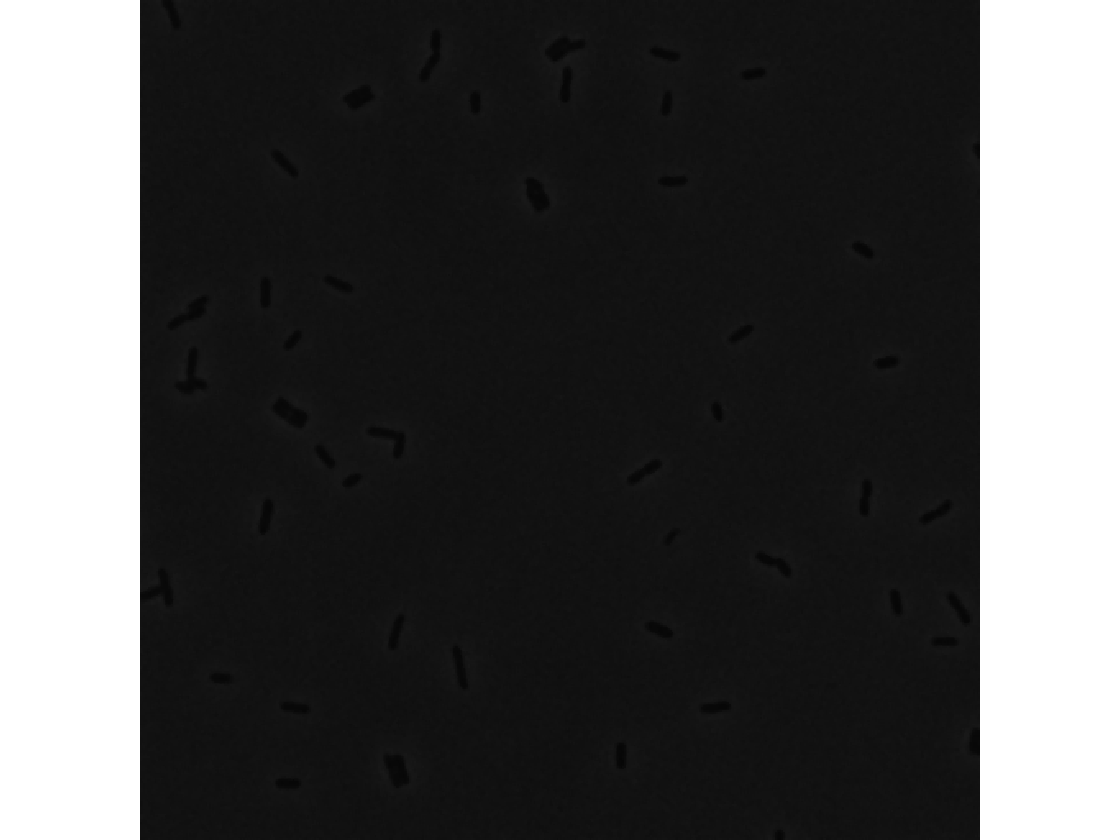

imshow(imPhase);

Running the above command shows a seemingly black image. However, if you use the "Data Cursor" icon in the image window and click around, you'll be able to see that the pixels actually have different values. We can scale the image to a certain range of values within the `imshow` directive.

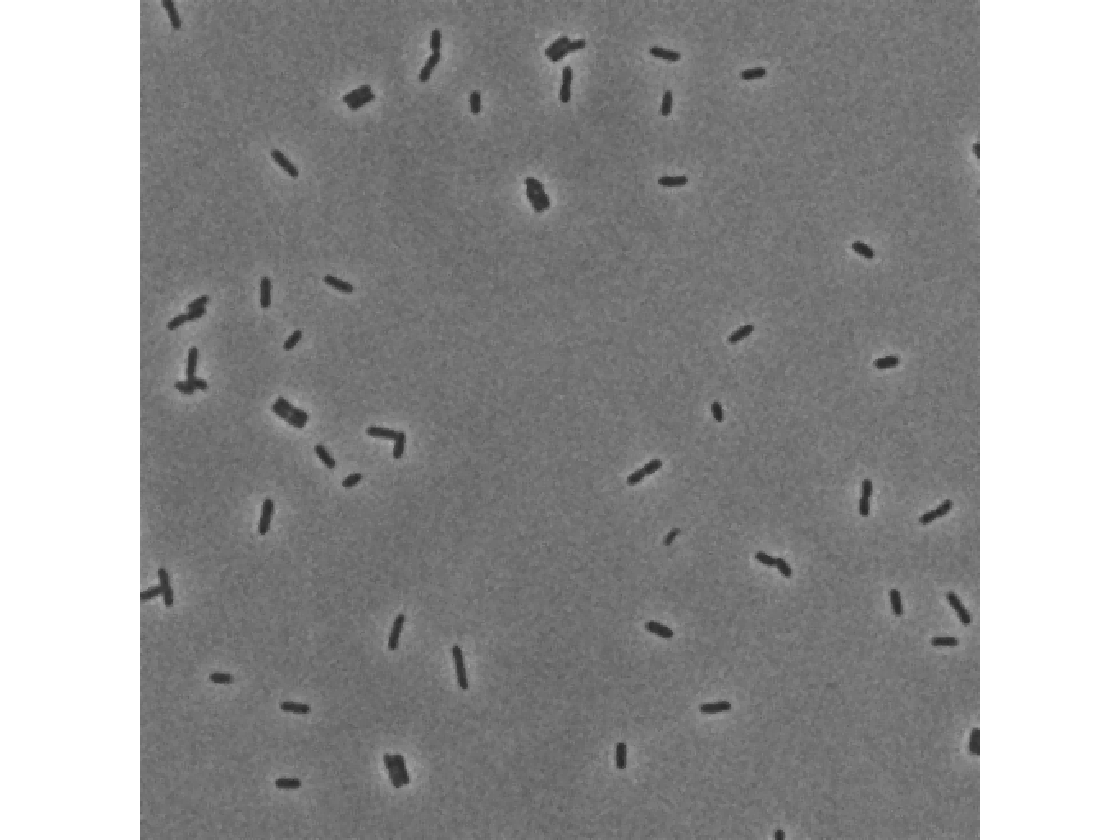

imshow(imPhase, [100, 10000])

The above command will display the image where the pixel value 100 or below will be black and 10000 or above will be white. To automatically scale the image such that the lowest pixel value is black and the highest is white, we can simply leave a pair of empty open/close brackets.

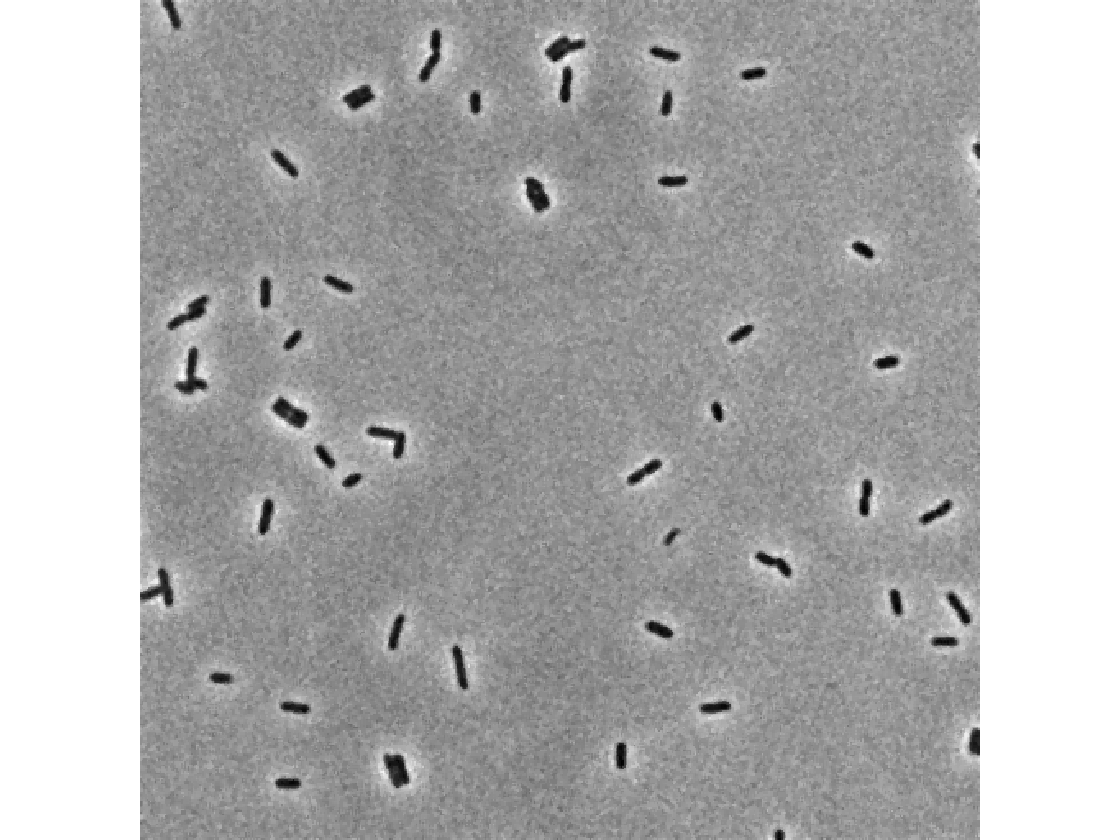

imshow(imPhase, [])

With phase contrast we can see that the pixel values for the bacteria themselves are much darker than the background. That should make us thing that if we were to find "how dark" are bacteria we could segment them out of the image just by setting a threshold value. This value would define that any pixel with a value below this number would be consider part of a cell, while any pixel with a value above would be part of the background.

For this is interesting to look at the distribution of pixel values. We can generate a histogram of all the numbers that are contained in our image by using the `imhist` function.

If we were apply this function directly to our 12-bit image since matlab thinks is a 16-bit image it would generate 216 bins for the histogram. In order to override that default option we will add an extra argument that is the number of bins we want for our histogram.

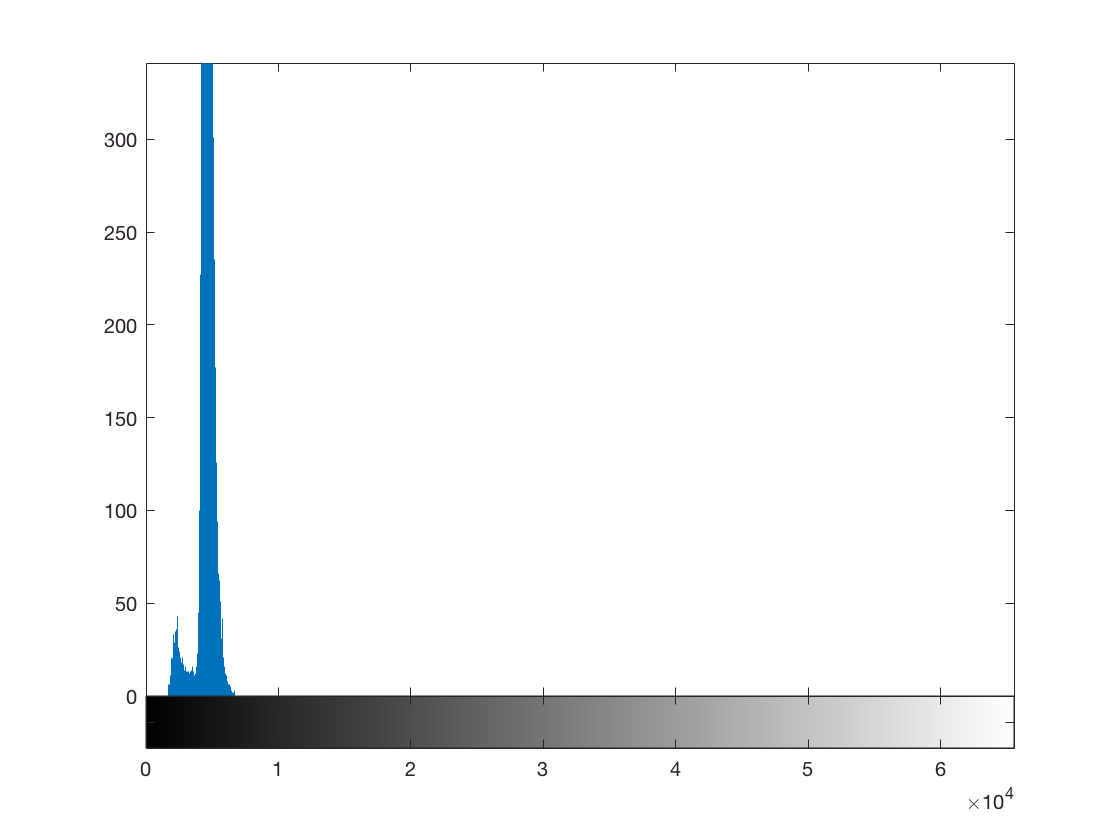

imhist(imPhase, 2^14);

The histogram looks very squished. It's hard to get a good hold on the range of values to choose a threshold. Let's rescale the x-axis so it only goes from the lowest to the highest value contained in the image.

To do this we first need to find this maximum and minimum pixel value. Since matlab likes to work in matrices if I were to use the `max` or the `min` functions that would return the maximum and minimum **of each column of the matrix**. But we want the **global**maximum or minimum. There are at least 2 ways to handle this in matlab:

- Use `max(max(imPhase))` such that the first `max` gets the maximum per column and the second one returns the maximum of these maximums.

- Use the trick to transform a 2D matrix into a 1D array `max(imPhase(:))`.

I personally think the second option is more elegant, so we'll stick with it.

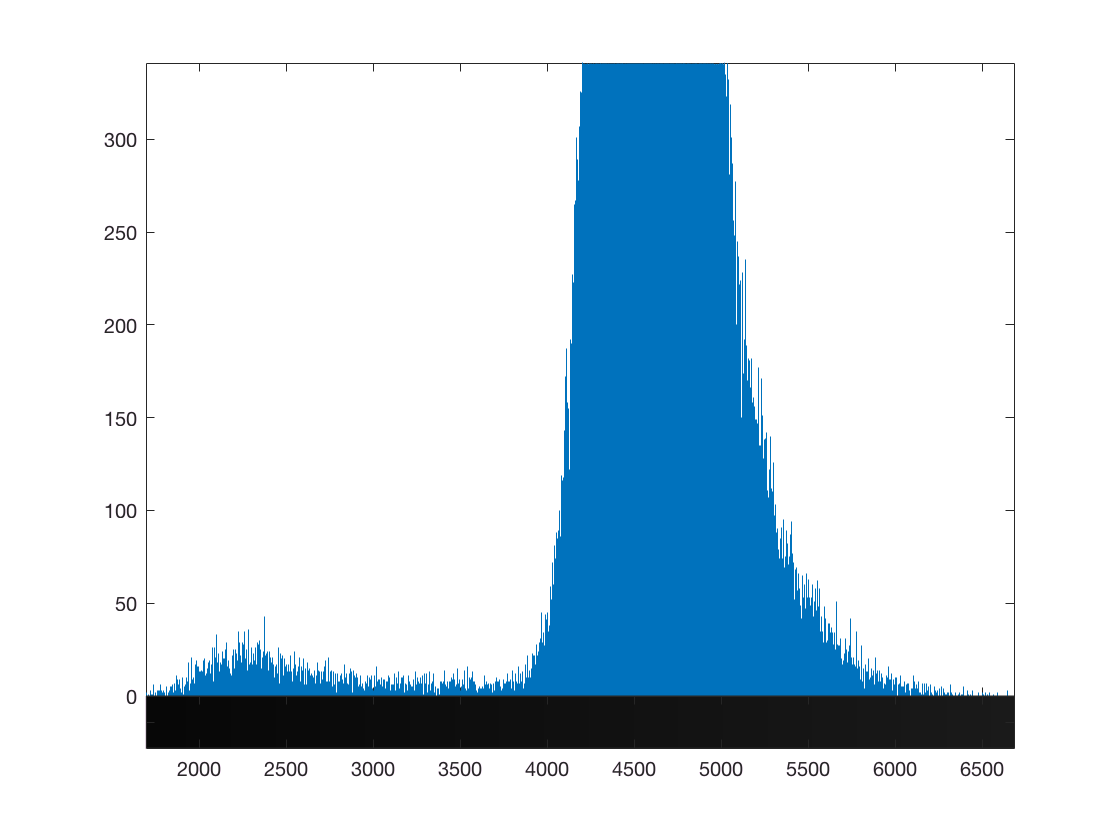

maxVal = max(imPhase(:));
minVal = min(imPhase(:));

imhist(imPhase, 2^14);
xlim([minVal, maxVal]);

We can see that there are roughly two peaks: One that corresponds to the bacteria pixels, and one that corresponds to the background.

The bacteria appeared as dark rods on a bright background. The peak at the lower pixel values therefore should correspond to the background.

Looking at the histogram, we see that a reasonable threshold to use would be 3500. Let's say that all the bacteria exist below this threshold. To look at this image, we'll use matlab's logic operations to find the pixels above a certain value. Below are some examples.

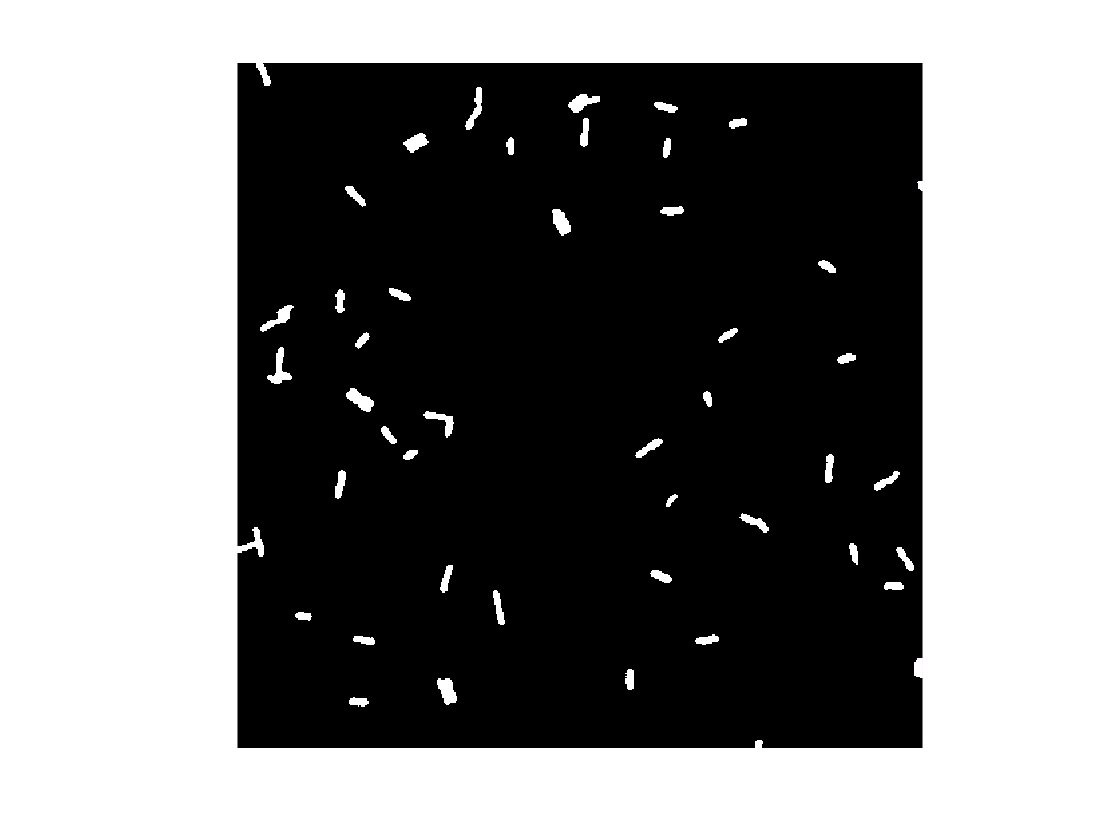

threshold = 3500;
imThresh = imPhase < threshold; % Generates binary image with 0 for the pixels
                                % greater than threshold and 1 for the rest.
imshow(imThresh);

Voila! This looks like a decent segmentation. There are fancier techniques that we could use to get a better result, but for now we will stick to this method.

One cool trick that I recently learn is that we can look at the differences between two images by using the function `imshowpair`. Let's look at it for fun.

The `imshowpair` image shows the difference between two images. What we will do is compare the phase contrast with our threshold image to see how well we did in terms of finding the cells

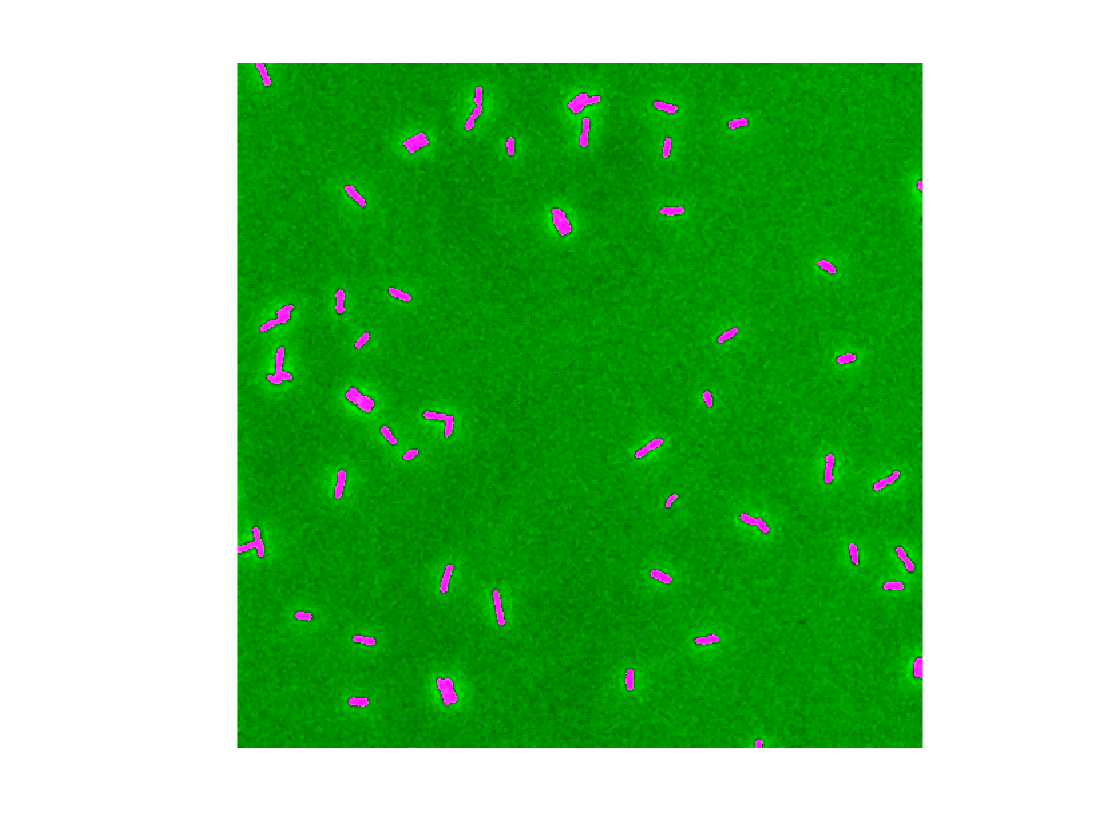

imshowpair(imPhase, imThresh)

Not too bad, right?